We solve for traffic flow using periodic boundary conditions. The following are parameters and a function relevant to defining the problem. 

rho_c = 1080;  rho_m = 380;  q_m = 10000;
Q0prime = @(rho) q_m*4*rho_c^2*(rho_c-rho_m)*rho_m ...
    *(rho_m-rho)./(rho*(rho_c-2*rho_m) + rho_c*rho_m).^3;
ep = 0.02;

Here we create a discretization on $m=800$ points.

[x,Dx,Dxx] = diffper(800,[0,4]);

Next we define the ODE resulting from the method of lines.

odefun = @(t,rho) -Q0prime(rho).*(Dx*rho) + ep*(Dxx*rho);

Our first initial condition has moderate density with a small bump.

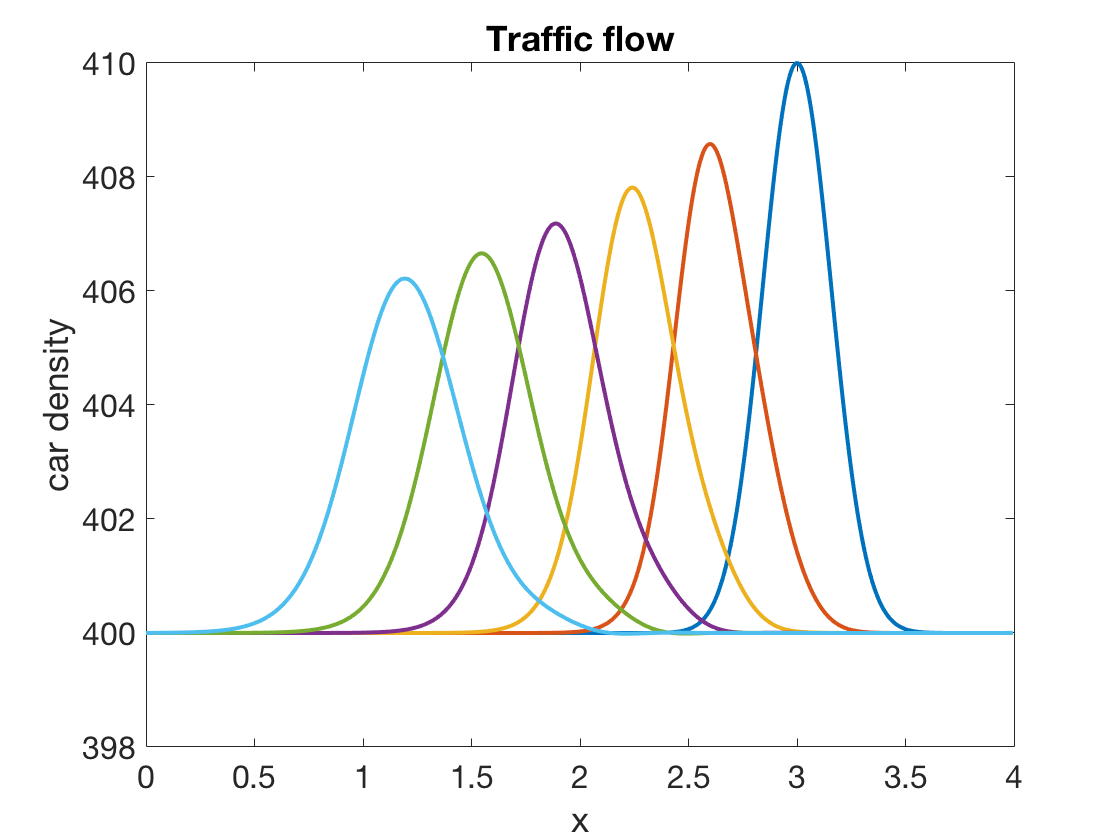

rho_init = 400 + 10*exp(-20*(x-3).^2);
t = linspace(0,1,6);
[t,RHO] = ode15s(odefun,t,rho_init);
plot(x,RHO)
xlabel('x'), ylabel('car density')    % ignore this line
title('Traffic flow')     % ignore this line

The bump slowly moves backward on the roadway, spreading out and gradually fading away due to the presence of diffusion.

Now we use an initial condition with a larger bump. 

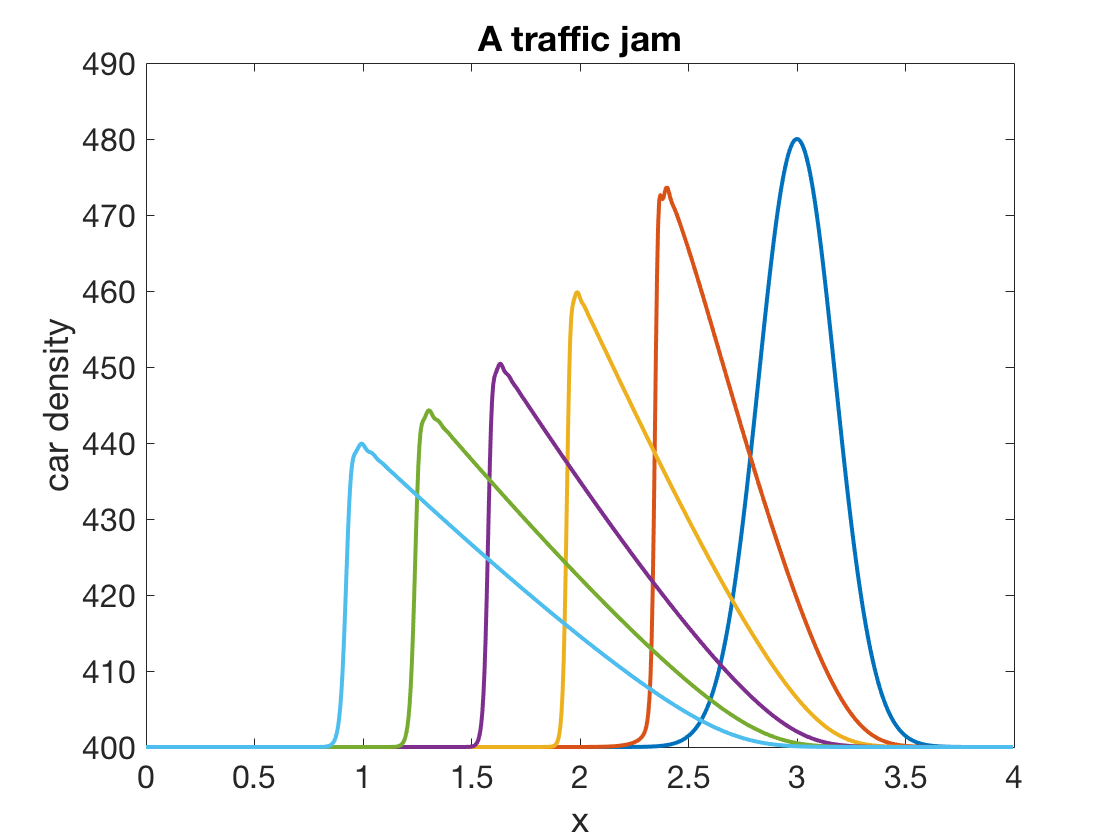

rho_init = 400 + 80*exp(-16*(x-3).^2);
t = linspace(0,0.5,6);
[t,RHO] = ode15s(odefun,t,rho_init);
plot(x,RHO)
xlabel('x'), ylabel('car density')    % ignore this line
title('A traffic jam')     % ignore this line

In this case the density bump travels backward along the road. It also steepens on the side facing the incoming traffic and decreases much more slowly on the other side. A motorist would experience this as an abrupt increase in density, followed by a much more gradual decrease in density and resulting gradual increase in speed.